# Laboratorium 4 - Krzywe parametryczne  

#### Zadanie 1

Napisz funkcję do rysowania krzywej Hermite'a zadanej punktami: początkowym $P_0$ i końcowym $P_1$oraz wektorami stycznymi w tych punktach $R_0$ i $R_1$

Zilustruj działanie funkcji dla następujących parametrów (nanieś na wykresy oprócz krzywej zadane punkty oraz wektory):

- 
$$P_0 =\left(1,1,0\right)\;\;\;P_1 =\left(4,1,0\right)\;\;\;R_0 =\left(-1,0,\;0\;\right)\;\;\;R_1 =\left(0,-1,0\right)$$


- 
$$P_0 =\left(1,1,0\right)\;\;\;P_1 =\left(4,1,0\right)\;\;\;R_0 =\left(-1,1,1\;\right)\;\;\;R_1 =\left(0,-1,-1\right)$$


- 
$$P_0 =\left(1,1,0\right)\;\;\;P_1 =\left(4,1,0\right)\;\;\;R_0 =\left(1,0,\;0\;\right)\;\;\;R_1 =\left(0,-1,0\right)$$


- 
$$P_0 =\left(1,1,0\right)\;\;\;P_1 =\left(4,1,1\right)\;\;\;R_0 =\left(1,0,\;0\;\right)\;\;\;R_1 =\left(1,0,0\right)$$


- 
$$P_0 =\left(1,1,0\right)\;\;\;P_1 =\left(4,1,0\right)\;\;\;R_0 =\left(1,0,\;0\;\right)\;\;\;R_1 =\left(-1,0,0\right)$$


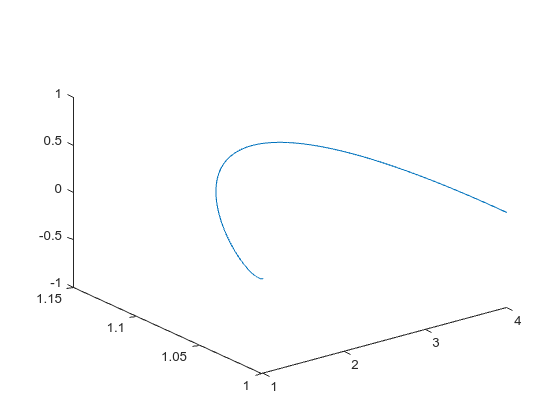

hermiteCurve([1, 1, 0], [4, 1, 0], [-1, 0, 0], [0, -1, 0]);

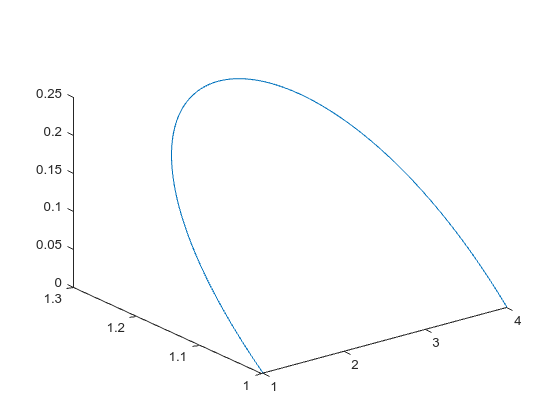

hermiteCurve([1, 1, 0], [4, 1, 0], [-1, 1, 1], [0, -1, -1]);

hermiteCurve([1, 1, 0], [4, 1, 0], [-1, 0, 0], [0, -1, 0]);

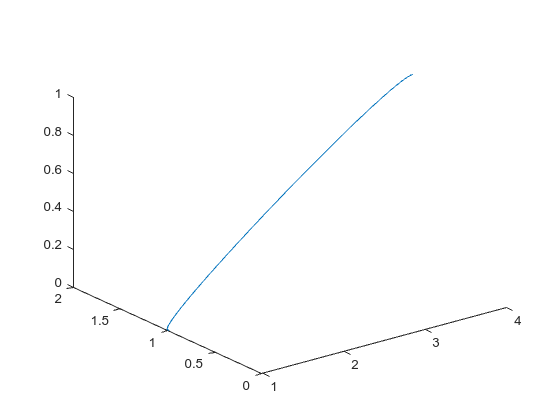

hermiteCurve([1, 1, 0], [4, 1, 1], [-1, 0, 0], [1, 0, 0]);

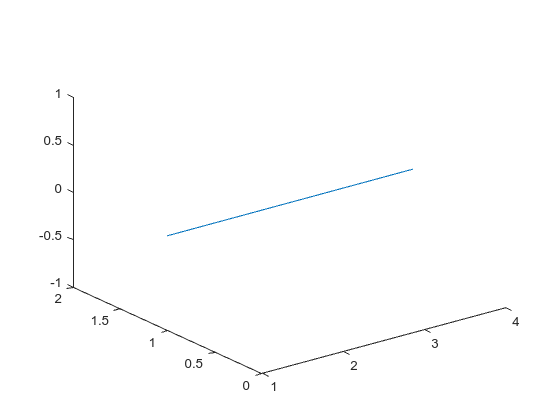

hermiteCurve([1, 1, 0], [4, 1, 0], [-1, 0, 0], [-1, 0, 0]);

#### Zadanie 2

Napisz funkcję do rysowania krzywej Beziera dla zbioru punktów zadanych macierzą:


$$P=\left\lbrack \begin{array}{ccc}
P_{0x}  & P_{0y}  & P_{0z} \\
P_{1x}  & P_{1y}  & P_{1z} \\
\cdots  & \cdots  & \cdots \\
P_{\textrm{nx}}  & P_{\textrm{ny}}  & P_{\textrm{nz}} 
\end{array}\right\rbrack$$
  

Zilustruj działanie funkcji dla następujących parametrów (nanieś na wykresy oprócz krzywej zadane punkty):   


$$P=\left\lbrack \begin{array}{ccc}
1 & 1 & 0\\
2 & 4 & 0\\
4 & 3 & 0\\
5 & 1 & 0
\end{array}\right\rbrack$$
       
$$P=\left\lbrack \begin{array}{ccc}
1 & 1 & 0\\
2 & 4 & 0\\
4 & 5 & 0\\
5 & 1 & 0
\end{array}\right\rbrack$$
      
$$P=\left\lbrack \begin{array}{ccc}
1 & 1 & 0\\
2 & 5 & 0\\
4 & 0 & 0\\
5 & 1 & 0
\end{array}\right\rbrack$$
      
$$P=\left\lbrack \begin{array}{ccc}
5 & 1 & 0\\
1 & 1 & 0\\
1 & 2 & 1\\
9 & 8 & 4\\
7 & 1 & 0\\
5 & 1 & 0
\end{array}\right\rbrack$$
      
$$P=\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 1 & 0\\
1 & 1 & 0\\
1 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 1\\
0 & 1 & 1\\
1 & 1 & 1\\
1 & 0 & 1\\
0 & 0 & 1
\end{array}\right\rbrack$$


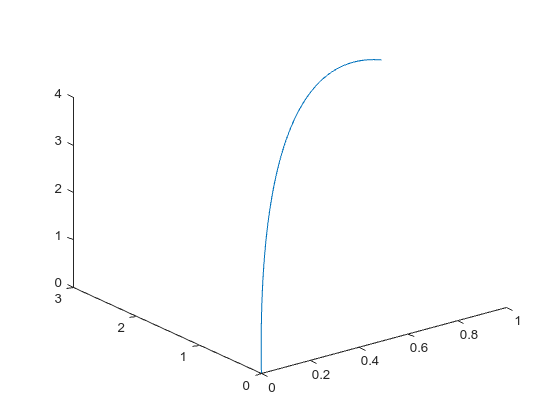

bezierCurve([1, 1, 0; 2, 4, 0; 4, 3, 0; 5, 1, 0])

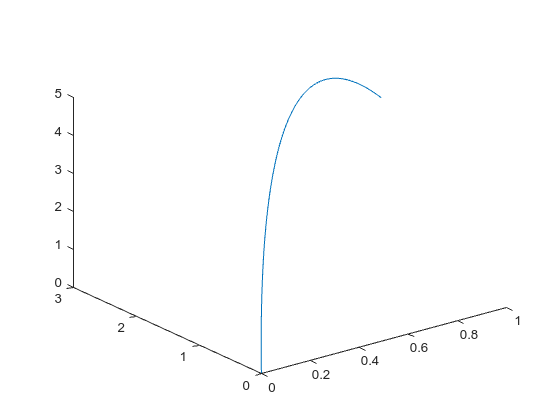

bezierCurve([1, 1, 0; 2, 4, 0; 4, 5, 0; 5, 1, 0])

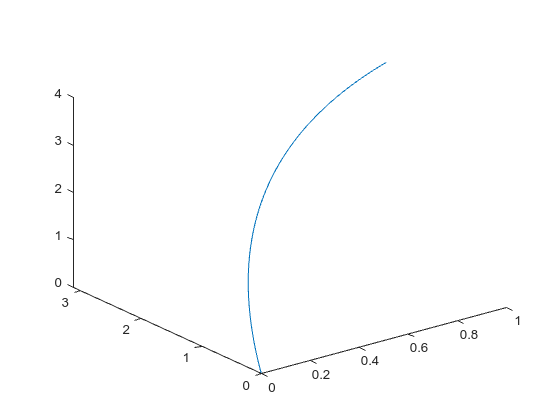

bezierCurve([1, 1, 0; 2, 5, 0; 4, 0, 0; 5, 1, 0])

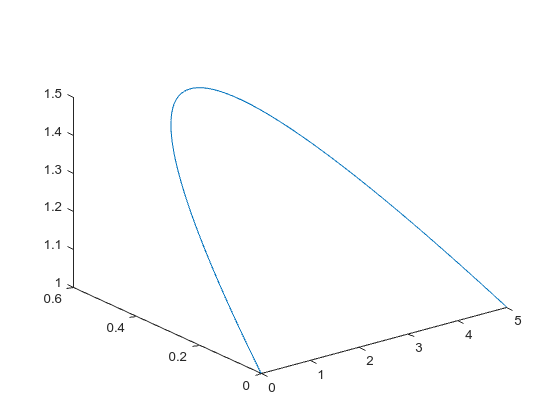

bezierCurve([5, 1, 0; 0, 1, 0; 1, 2, 1; 9, 8, 4; 7, 1, 0; 5, 1, 0])

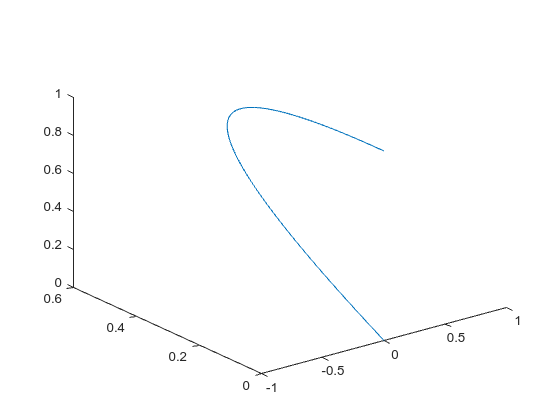

bezierCurve([0, 0, 0; 0, 1, 0; 1, 1, 0; 1, 0, 0; 0, 0, 0; 0, 0, 1; 0, 1, 1; 1, 1, 1; 1, 0, 1; 0, 0, 1])

#### Zadanie 3

Zmodyfikuj funkcję do rysowania krzywej Hermita dla zbioru punktów zadanych macierzą $P$ jak w zadaniu 2. Wykorzystaj funkcję z zadania 1 do rysowania poszczególnych bloków $i$ krzywej:  

$P_i$  ,  $P_{i+1}$  , $R_i =P_{i+1} -P_i$   ,   $R_{i+1} =P_{i+2} -P_{i+1}$   dla  $i=0\;$

$P_i$  ,  $P_{i+1}$  , $R_i =P_i -P_{i-1}$   ,   $R_{i+1} =P_{i+2} -P_{i+1}$   dla  $i=1\;\ldotp \ldotp \ldotp n-2$

$P_i$  ,  $P_{i+1}$  , $R_i =P_i -P_{i-1}$   ,   $R_{i+1} =P_{i+1} -P_i$   dla  $i=1\;\ldotp \ldotp \ldotp n-1$

Narysuj przebieg krzywej dla zestawów punktów z zadania 2. Porównaj przebieg krzywej z odpowiednią krzywą Beziera z zadania 2.  

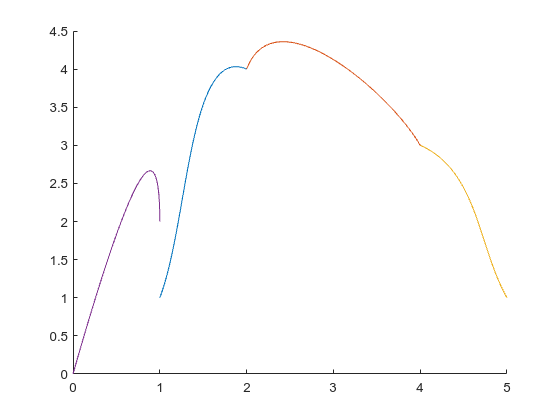

figure
hold on
hermiteCurveMatrix([1, 1, 0; 2, 4, 0; 4, 3, 0; 5, 1, 0])
bezierCurve([1, 1, 0; 2, 4, 0; 4, 3, 0; 5, 1, 0])
hold off

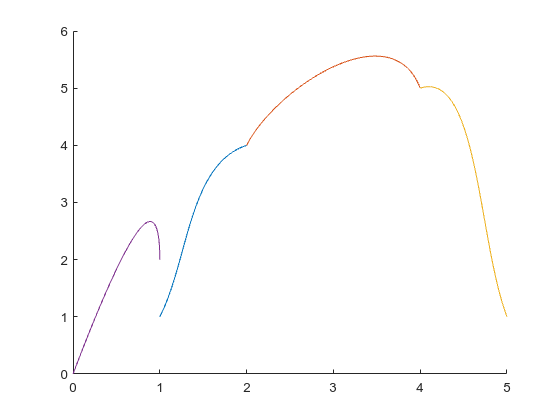


figure
hold on
hermiteCurveMatrix([1, 1, 0; 2, 4, 0; 4, 5, 0; 5, 1, 0])
bezierCurve([1, 1, 0; 2, 4, 0; 4, 5, 0; 5, 1, 0])
hold off

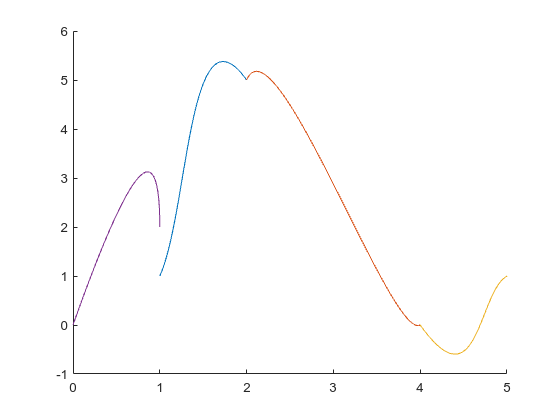


figure
hold on
hermiteCurveMatrix([1, 1, 0; 2, 5, 0; 4, 0, 0; 5, 1, 0])
bezierCurve([1, 1, 0; 2, 5, 0; 4, 0, 0; 5, 1, 0])
hold off

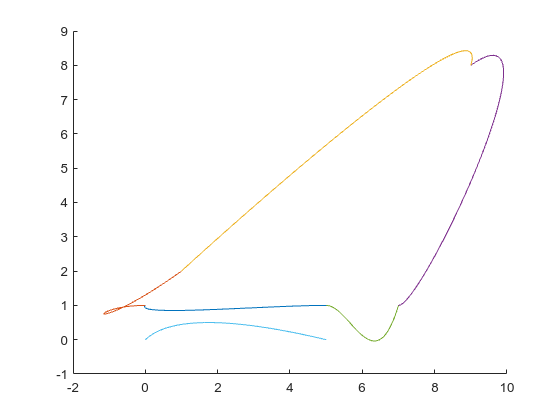


figure
hold on
hermiteCurveMatrix([5, 1, 0; 0, 1, 0; 1, 2, 1; 9, 8, 4; 7, 1, 0; 5, 1, 0])
bezierCurve([5, 1, 0; 0, 1, 0; 1, 2, 1; 9, 8, 4; 7, 1, 0; 5, 1, 0])
hold off

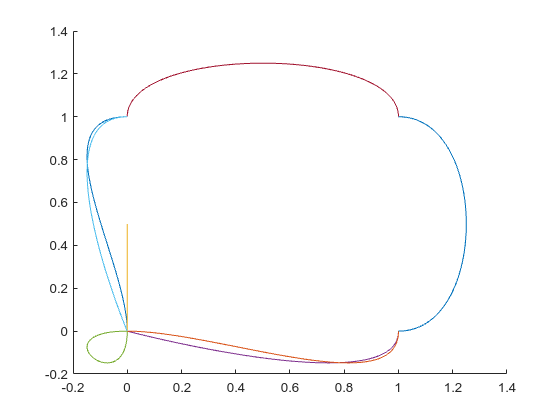


figure
hold on
hermiteCurveMatrix([0, 0, 0; 0, 1, 0; 1, 1, 0; 1, 0, 0; 0, 0, 0; 0, 0, 1; 0, 1, 1; 1, 1, 1; 1, 0, 1; 0, 0, 1])
bezierCurve([0, 0, 0; 0, 1, 0; 1, 1, 0; 1, 0, 0; 0, 0, 0; 0, 0, 1; 0, 1, 1; 1, 1, 1; 1, 0, 1; 0, 0, 1])
hold off

function hermiteCurve(P0, P1, R0, R1)
    t = linspace(0, 1, 100);
    
    H00 = 2 * t.^3 - 3 * t.^2 + 1;
    H10 = t.^3 - 2 * t.^2 + t;
    H01 = -2 * t.^3 + 3 * t.^2;
    H11 = t.^3 - t.^2;
    
    x = H00 * P0(1) + H10 * R0(1) + H01 * P1(1) + H11 * R1(1);
    y = H00 * P0(2) + H10 * R0(2) + H01 * P1(2) + H11 * R1(2);
    z = H00 * P0(3) + H10 * R0(3) + H01 * P1(3) + H11 * R1(3);
    
    plot3(x, y, z);
end

function bezierCurve(P)
    t = linspace(0, 1, 100);
    n = size(P, 2);  
    
    B = zeros(n, length(t));
    for i = 0:n-1
        B(i+1, :) = nchoosek(n-1, i) * t.^i .* (1 - t).^(n-1 - i);
    end
    
    x = sum(P(1, :)' .* B);
    y = sum(P(2, :)' .* B);
    z = sum(P(3, :)' .* B);
    
    plot3(x, y, z);
end

function hermiteCurveMatrix(P)
    n = size(P, 1);

    for i = 0:n-2
        P0 = P(i+1, :);
        P1 = P(i+2, :);
        
        if i == 0
            R0 = P1 - P0;
            R1 = P(i+3, :) - P1;
        elseif i == n-2
            R0 = P0 - P(i, :);
            R1 = P1 - P0;
        else
            R0 = P0 - P(i, :);
            R1 = P(i+3, :) - P1;
        end
        
        t = linspace(0, 1, 100);
        
        H00 = 2 * t.^3 - 3 * t.^2 + 1;
        H10 = t.^3 - 2 * t.^2 + t;
        H01 = -2 * t.^3 + 3 * t.^2;
        H11 = t.^3 - t.^2;
        
        x = H00 * P0(1) + H10 * R0(1) + H01 * P1(1) + H11 * R1(1);
        y = H00 * P0(2) + H10 * R0(2) + H01 * P1(2) + H11 * R1(2);
        z = H00 * P0(3) + H10 * R0(3) + H01 * P1(3) + H11 * R1(3);
        
        plot3(x, y, z);
    end
end
